clear all;
clc;
load("mnist-matlab.mat")

for i= 1:size(X_train,1)
    XTrain(:,1,1,i) = X_train(i,:);
end
for i= 1:size(X_test,1)
    XTest(:,1,1,i) = X_test(i,:);
end

classNames = categories(y_train);
numClasses = numel(classNames);
numObservations = numel(y_train);

## Parameters

W{1} = dlarray(initializeGaussian([1000,size(X_train,2)]));
B{1} = dlarray(initializeGaussian([1000,size(X_train,2)]));
b{1} = dlarray(zeros(1000,1,'single'));

W{2} = dlarray(initializeGaussian([1000,1000]));
B{2} = dlarray(initializeGaussian([1000,size(X_train,2)]));
b{2} = dlarray(zeros(1000,1,'single'));

W{3} = dlarray(initializeGaussian([numClasses,1000]));
b{3} = dlarray(zeros(numClasses,1,'single'));

parameters = [W,b]

parameters = 1×6 cell array
    {1000×784 dlarray}    {1000×1000 dlarray}    {10×1000 dlarray}    {1000×1 dlarray}    {1000×1 dlarray}    {10×1 dlarray}


## Specify Training Options

numEpochs = 10;
miniBatchSize = 2000;
plots = "training-progress";
numIterationsPerEpoch = floor(numObservations./miniBatchSize);
executionEnvironment = "auto";
learning_rate = 1e-4;

## Train Model

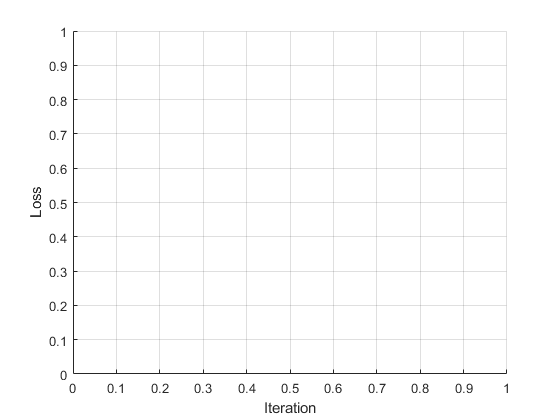

if plots == "training-progress"
    figure

    lineLossTrain = animatedline('Color',[0.85 0.325 0.098]);
    ylim([0 inf])
    xlabel("Iteration")
    ylabel("Loss")
    grid on
end

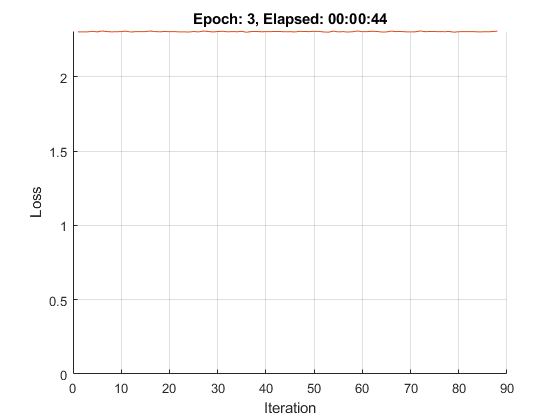


vel = [];
iteration = 0;
start = tic;

% Loop over epochs.
for epoch = 1:numEpochs
    
    % Shuffle data.
    idx = randperm(numObservations);
    XTrain = XTrain(:,:,:,idx);
    y_train = y_train(idx);
    
    % Loop over mini-batches
    for i = 1:numIterationsPerEpoch
        iteration = iteration + 1;
        idx = (i-1)*miniBatchSize+1:i*miniBatchSize;
        
        % Read mini-batch of data and convert the labels to dummy
        % variables.
        X = XTrain(:,:,:,idx);
        
        Y1 = zeros(numClasses, miniBatchSize, 'single');
        for c = 1:numClasses
            Y1(c,y_train(idx)==classNames(c)) = 1;
        end
        
        
        % Convert mini-batch of data to dlarray.
        dlX = dlarray(X,'SSCB');
        
        % If training on a GPU, then convert data to gpuArray.
        if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
            dlX = gpuArray(dlX);
        end
        
        % get final output from model
        [Aout, Hout, Yout] = model(dlX,W,b);
         
        
        % pass output to calculate loss and gradient
        [gradients,loss] = dlfeval(@modelGradients, Yout, Y1, parameters);
        
        % Update the network parameters using the SGDM optimizer.
        [parameters, vel] = sgdmupdate(parameters, gradients, vel);
        
        % Display the training progress.
        if plots == "training-progress"
            D = duration(0,0,toc(start),'Format','hh:mm:ss');
            addpoints(lineLossTrain,iteration,double(gather(extractdata(loss))))
            title("Epoch: " + epoch + ", Elapsed: " + string(D))
            drawnow
        end
    end
end

## Test Model

dlXTest = dlarray(XTest,'SSCB');
if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
    dlXTest = gpuArray(dlXTest);
end
dlYPred = model(dlXTest, parameters);

Evaluate the classification accuracy.

[~,idx] = max(extractdata(dlYPred),[],1);
labelsPred = categorical(classNames(idx));
accuracy = mean(labelsPred==y_test)

## Model Function

function [a, h, y] = model(dlX,Win,bin)

a{1} = fullyconnect(dlX, Win{1}, bin{1});
h{1} = sigmoid(a{1});

a{2} = fullyconnect(h{1},Win{2},bin{2});
h{2} = sigmoid(a{2});

a{3} = fullyconnect(h{2}, Win{3}, bin{3});
y = softmax(a{3});

end

## Model Gradients Function

function [gradients,loss] = modelGradients(out,T1,parameters)
lossLabels = crossentropy(out,T1);

loss = lossLabels;
numgrad = numel(parameters);

gradients{6} = dlgradient(lossLabels, parameters{6});
gradients{5} = dlgradient(lossLabels, parameters{5});
gradients{1} = parameters{1};
gradients{2} = parameters{2};
gradients{3} = parameters{3};
gradients{4} = parameters{4};


end

## Weights Initialization Function

The `initializeGaussian` function samples weights from a Gaussian distribution with mean 0 and standard deviation 0.01.

function parameter = initializeGaussian(sz)
parameter = randn(sz,'single').*0.01;
end

## **Parameter Update Function**

function updated = updateparam(parameters, Bs, e, As)

delA{2} = B{2}*e 

end

## Sigmoid Derivative Function

function Y = sigmoid_derive(X)
 Y = sigmoid(X).*(1-sigmoid(X));
end 